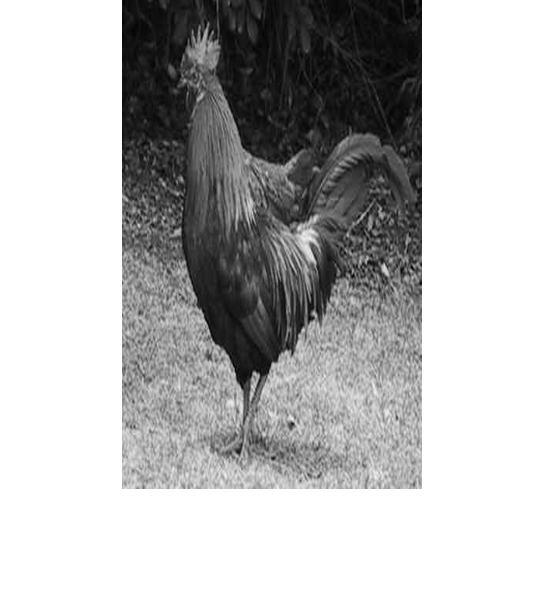

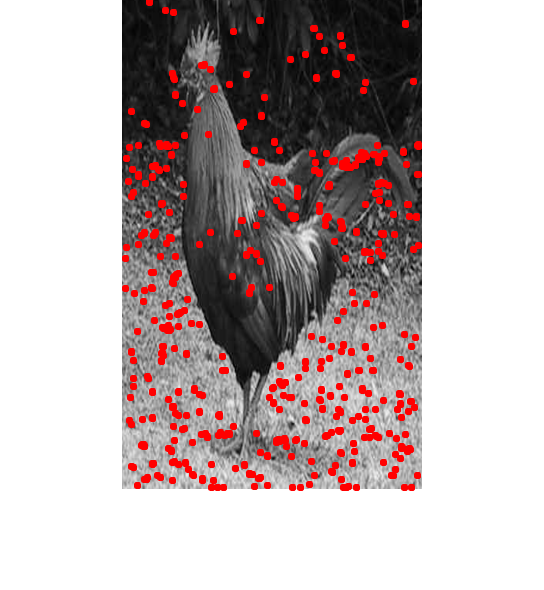

close all
clear all
 
I = imread('rooster.jpg');
I = rgb2gray(I);
I = imresize(I,[500,300]);
imshow(I);
 
sigma = 1;
halfwid = sigma * 3;
 
[xx, yy] = meshgrid(-halfwid:halfwid, -halfwid:halfwid);
 
Gxy = exp(-(xx .^ 2 + yy .^ 2) / (2 * sigma ^ 2));
Gx = xx .* exp(-(xx .^ 2 + yy .^ 2) / (2 * sigma ^ 2));
Gy = yy .* exp(-(xx .^ 2 + yy .^ 2) / (2 * sigma ^ 2));
 
%%apply sobel in herizontal direction and vertical direction compute the
%%gradient
%fx = [-1 0 1;-1 0 1;-1 0 1];
%fy = [1 1 1;0 0 0;-1 -1 -1];
Ix = conv2(I,Gx,'same');
Iy = conv2(I,Gy,'same');
%%compute Ix2, Iy2,Ixy
Ix2 = Ix.*Ix;
Iy2 = Iy.*Iy;
Ixy = Ix.*Iy;
 
%%apply gaussian filter
h = fspecial('gaussian',[6,6],1);
Ix2 = conv2(Ix2,h,'same');
Iy2 = conv2(Iy2,h,'same');
Ixy = conv2(Ixy,h,'same');
height = size(I,1);
width = size(I,2);
result = zeros(height,width);
R = zeros(height,width);
Rmax = 0;
%% compute M matrix and corner response
for i = 1:height
    for j =1:width
        M = [Ix2(i,j) Ixy(i,j);Ixy(i,j) Iy(i,j)];
        R(i,j) = det(M) - 0.04*(trace(M)^2);
        if R(i,j)> Rmax
            Rmax = R(i,j);
        end
    end
end
%% compare whith threshold
count = 0;
for i = 2:height-1
    for j = 2:width-1
        if R(i,j) > 0.01*Rmax
            result(i,j) = 1;
            count = count +1;
        end
    end
end
 
%non-maxima suppression
result = imdilate(result, [1 1 1; 1 0 1; 1 1 1]);
 
[posc,posr] = find(result == 1);
imshow(I);
hold on;
plot(posr,posc,'r.');